clear;clc;close all;
tempo = 0;
degrau = 0;
resposta = 0;


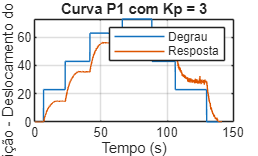

% Gráfico P1
figure(1)
plot(tempo, degrau), grid on; hold on;
plot(tempo, resposta), hold off;
title('Curva P1 com Kp = 3');
xlabel('Tempo (s)');
ylabel('Posição - Deslocamento do Pistão');
legend('Degrau', 'Resposta');

%% ====== MODO MANUAL (opcional) =======================================
% Se preferir digitar apenas os tempos de 63,2%% e níveis:
Kp = 3;

t0   = [6.599 22.999 41.699];    % instante do degrau em cada curva
t632 = [7.8 26.299 45.200];   % tempo quando atingiu 63,2%% (cada curva)
y0   = [0 14.645 35.420];            % saída antes do degrau
yinf = [14.645 35.420 56.320];      % saída final
r0 = [0 22.861 42.861];          % nível de referência antes
r1 = [22.861 42.861 62.861];     % nível de referência depois

Dr = r1 - r0;  Dy = yinf - y0;
Kcl_vec   = Dy ./ Dr;
taucl_vec = t632 - t0;
K_vec   = Kcl_vec ./ (Kp*(1 - Kcl_vec));
tau_vec = taucl_vec ./ (1 - Kcl_vec);

K_avg  = mean(K_vec);  tau_avg = mean(tau_vec);
s = tf('s');  Gp_avg = K_avg/(tau_avg*s+1);  T_avg = feedback(Kp*Gp_avg,1);